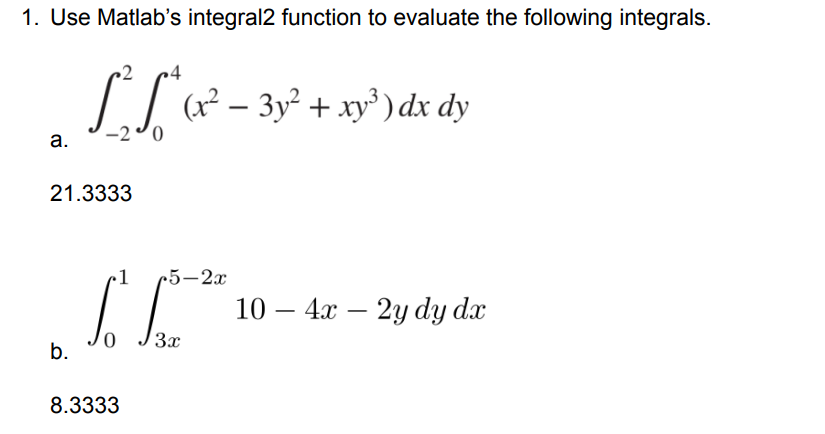

%NOTE: Basically integral2 works by integrating twice, order doesn't matter
%but make sure that x limits are evaluated when when dx and vice versa
%Dont forget the dot notation (element wise) (unless symbolic or else)

%Q1 (a)
f = @(x, y) x.^2 - (3.*y.^2) + (x.*y.^3)

f = function_handle with value:
    @(x,y)x.^2-(3.*y.^2)+(x.*y.^3)


def_integral = integral2(f, 0, 4, -2, 2)

def_integral = 21.3333

disp([num2str(def_integral)]);

21.3333


%   (b)
f = @(x, y) 10 - 4*x - 2*y

f = function_handle with value:
    @(x,y)10-4*x-2*y


def_integral = integral2(f,0, 1,@(x) 3*x ,@(x) 5-2*x)

def_integral = 8.3333


%First two values are scalar. Based on equation, you have to manipulate. 

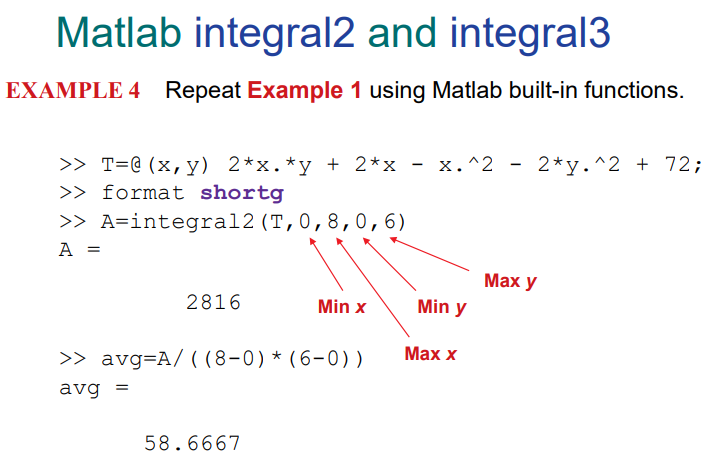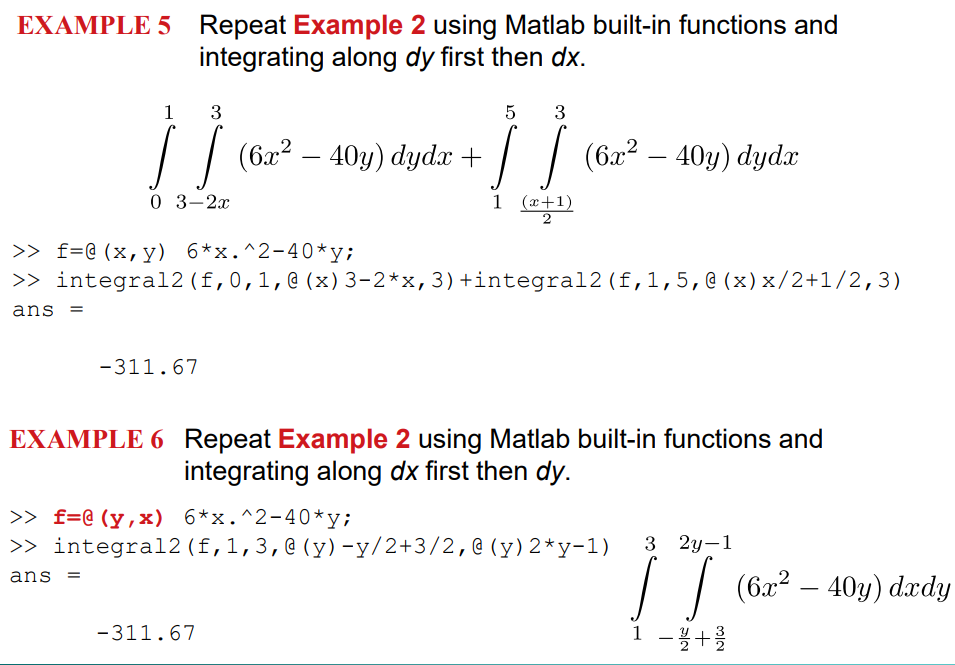

%Q2 (a)
f = @(x, y, z) x.^3 - (2.*y.*z)

f = function_handle with value:
    @(x,y,z)x.^3-(2.*y.*z)


def_integral = integral3(f,-1, 3, 0, 6, -4, 4)

def_integral = 960

%   (b)
f = @(x,y,z) 6.*z.^2

f = function_handle with value:
    @(x,y,z)6.*z.^2


def_integral = integral3(f, 0, 2.5, 0, @(x) 10 - 4*x, 0, @(x, y) 5 - 2*x - y/2)

def_integral = 312.5000


%Be careful of limits (outside correspond to furhtermost)

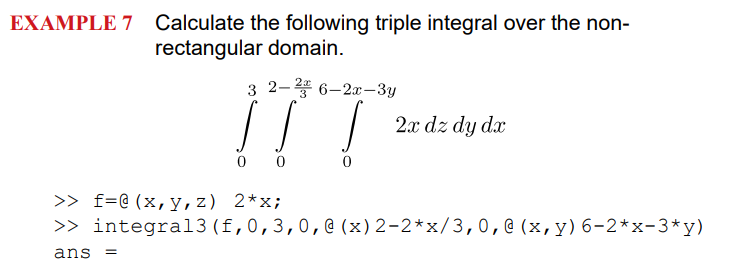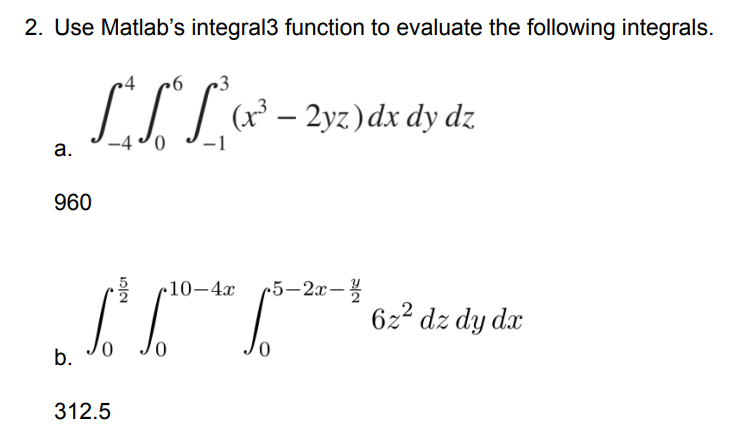

format long;
H = 30;
F = @(z) 200.*(z ./ (5+z)) .* exp((-2.*z) ./H);
def_integral = integral(F, 0, H)

def_integral =      1.480568480085906e+03


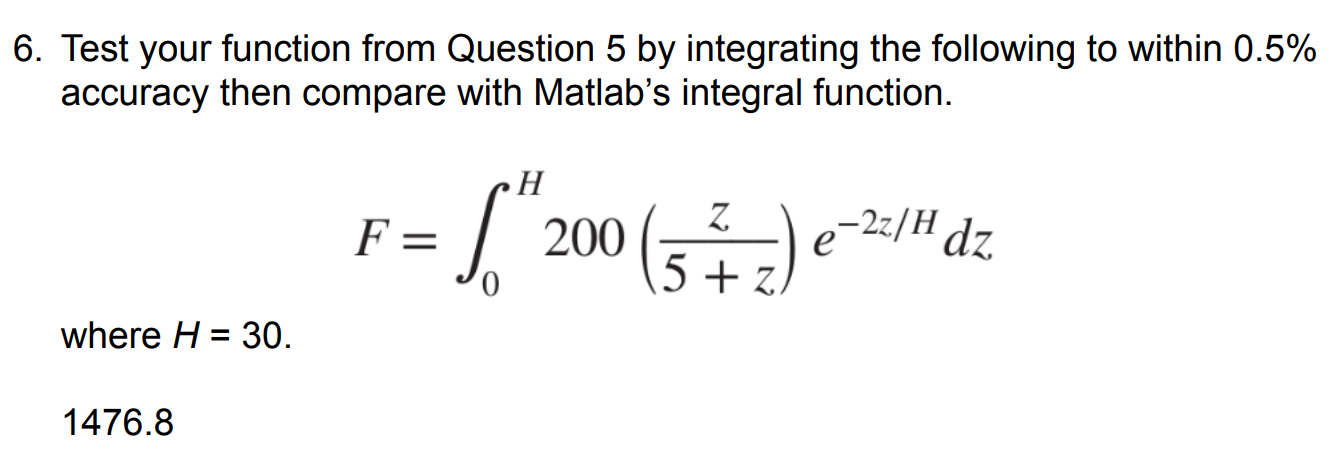

H = 30;
F = @(z) (200 * (z ./ (5 + z)) .* exp(-2 * z / H));
S = RombergIntegration(F, 0, H, 0.005);  % Use 0.005 for 0.5% accuracy
True = integral(F, 0, 30);

% Display the results
disp(['Approximation of the integral: ' num2str(S)]);

Approximation of the integral: 1479.8107


disp(['True integral value using MATLAB integral: ' num2str(True)]);

True integral value using MATLAB integral: 1480.5685


format long
y = @(x) 0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;
True = integral(y, 0, 0.8)

True =    1.640533333333332



accuracy = 0.001;

% Call the RombergIntegration function
result = RombergIntegration(y, 0, 0.8, accuracy);

% Display the result
disp(['Approximation of the integral: ' num2str(result)]);

Approximation of the integral: 1.6404



Error = (abs(True - result) / True) * 100

Error =    0.009524093647666




%Below are two pictures: both for error calculation: Ra error, Simpson's
%error with n = 2.


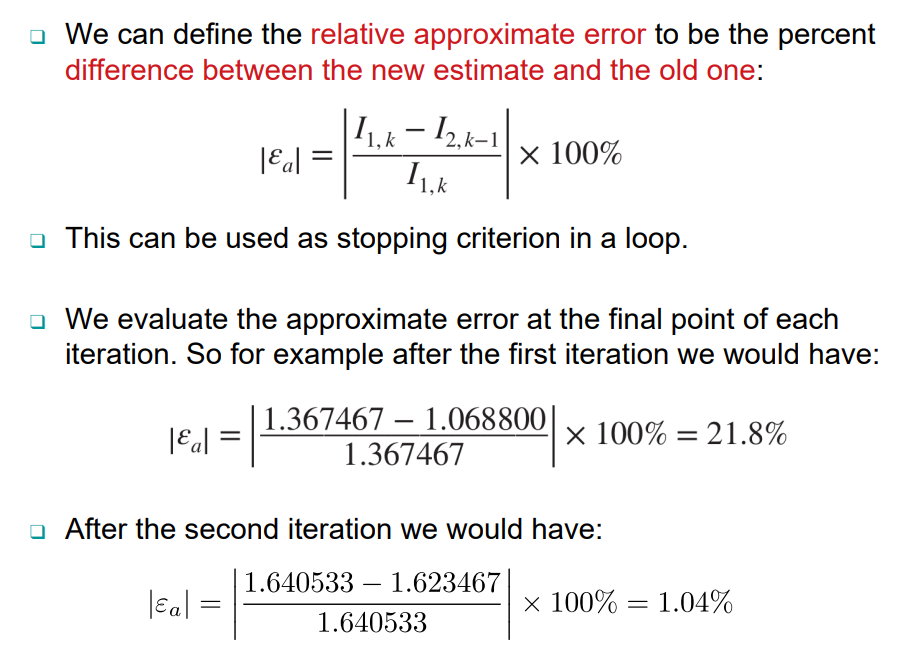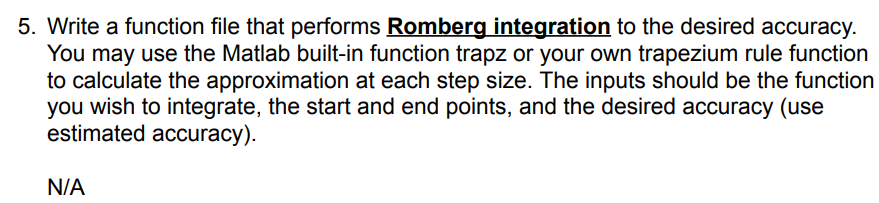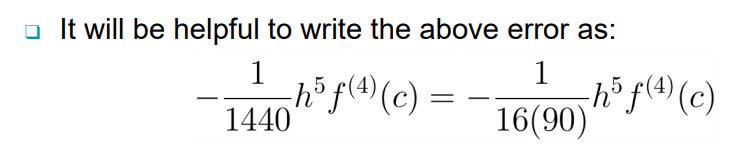

function R = Richardson(fun, a, b)
    %Order of h2 first
    h = 0.8;
    n = (b-a)/h;
    
    Ih1 = CompTrapezium(fun, a, b, n*2);
    Ih2 = CompTrapezium(fun, a, b, n*4);

    R = ((4*Ih2) - Ih1) / 3;


    True = integral(fun, a, b)
    Et = (abs(True - R) / True) * 100

end


function I = RombergIntegration(fun, a, b, accuracy)
    format long;
    % Initialize variables
    n = 1;  % Initial number of segments
    h = b - a;
    I_prev = (h / 2) * (fun(a) + fun(b));
    
    while true
        % Double the number of segments
        n = 2 * n;
        h = h / 2;
        
        % Calculate the new approximation using CompTrapezium
        I = CompTrapezium(fun, a, b, n);
        
        % Calculate the estimated accuracy
        est_accuracy = abs((I - I_prev) / I);
        
        % Check if the estimated accuracy is below the desired accuracy
        if est_accuracy < accuracy
            return;
        end
        
        % Update the previous approximation
        I_prev = I;
    end
end


%Function implemented without error calculation.
function I = CompTrapezium(fun, a, b, n)
    h = (b - a) / n;
    I = (fun(a) + fun(b)) / 2;
    for i = 1:n-1
        x = a + (i * h);
        I = I + fun(x); 
    end
    I = I * h; 
end

%Monte Carlo down below -->